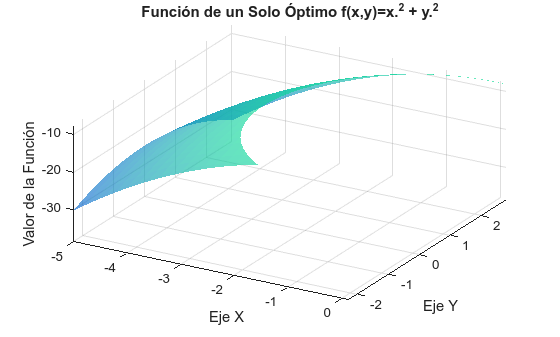

% ==========================================================
% APLICACIÓN DEL ALGORITMO HILL CLIMBING CON UN SOLO ÓPTIMO
% Prof. Aboud BARSEKH-ONJI (D.Sc.)
% Email: aboud.barsekh@anahuac.mx
% https://orcid.org/0009-0004-5440-8092
% Universidad Anáhuac México Sur - Facultad de Ingeniería 
% ==========================================================

% 1. Definición de la Función Objetivo
% Usamos un paraboloide invertido, una función simple con un único máximo.
% El objetivo es maximizar esta función.
funcion_objetivo = @(x, y) -(x.^2 + y.^2);
% Visualizar la función
figure; % Creamos una nueva figura
hold on; % Mantenemos los elementos gráficos en la misma figura
grid on;
title('Función de un Solo Óptimo f(x,y)=x.^2 + y.^2');
xlabel('Eje X');
ylabel('Eje Y');
zlabel('Valor de la Función');
view(30, 45); % Ángulo de la vista 3D
% Graficamos la superficie de la función
[x, y] = meshgrid(-5:0.2:5, -5:0.2:5);
z = funcion_objetivo(x, y);
surf(x, y, z, 'FaceAlpha', 0.6, 'EdgeColor', 'none');
colormap(winter);


% 2. Parámetros del Algoritmo
limite_x = [-5, 5]; % Límites para el eje x
limite_y = [-5, 5]; % Límites para el eje y
tamano_paso = 0.01;  % Magnitud del movimiento en cada iteración
max_iteraciones = 500; % Número máximo de pasos para evitar bucles infinitos

% --- 3. Inicialización ---
% Empezamos en un punto aleatorio dentro de los límites definidos.
punto_actual_x = limite_x(1) + (limite_x(2) - limite_x(1)) * rand();
punto_actual_y = limite_y(1) + (limite_y(2) - limite_y(1)) * rand();
valor_actual = funcion_objetivo(punto_actual_x, punto_actual_y);

% Guardamos el historial de puntos para luego graficarlos.
historial_puntos = [punto_actual_x, punto_actual_y, valor_actual];

% --- 4. Algoritmo Hill Climbing ---
disp('Iniciando búsqueda de Hill Climbing para función de un solo óptimo...');

Iniciando búsqueda de Hill Climbing para función de un solo óptimo...


for i = 1:max_iteraciones
    
    % Generamos los puntos vecinos (8 direcciones posibles)
    vecinos = [punto_actual_x + tamano_paso, punto_actual_y; ...
               punto_actual_x - tamano_paso, punto_actual_y; ...
               punto_actual_x, punto_actual_y + tamano_paso; ...
               punto_actual_x, punto_actual_y - tamano_paso; ...
               punto_actual_x + tamano_paso, punto_actual_y + tamano_paso; ...
               punto_actual_x - tamano_paso, punto_actual_y - tamano_paso; ...
               punto_actual_x + tamano_paso, punto_actual_y - tamano_paso; ...
               punto_actual_x - tamano_paso, punto_actual_y + tamano_paso];

    % Evaluamos la función en todos los puntos vecinos
    valores_vecinos = funcion_objetivo(vecinos(:,1), vecinos(:,2));
    
    % Encontramos el mejor vecino
    [mejor_valor_vecino, indice_mejor] = max(valores_vecinos);
    mejor_vecino = vecinos(indice_mejor, :);

    % Comparamos el mejor vecino con el punto actual
    if mejor_valor_vecino > valor_actual
        % Si el vecino es mejor, nos movemos a ese punto
        punto_actual_x = mejor_vecino(1);
        punto_actual_y = mejor_vecino(2);
        valor_actual = mejor_valor_vecino;
        
        % Guardamos el nuevo punto en el historial
        historial_puntos = [historial_puntos; punto_actual_x, punto_actual_y, valor_actual];
    else
        % Si no hay un vecino mejor, hemos llegado a la cima.
        disp('Se ha alcanzado el óptimo. El algoritmo termina.');
        break; % Salimos del bucle
    end
end

Se ha alcanzado el óptimo. El algoritmo termina.



if i == max_iteraciones
    disp('Se alcanzó el número máximo de iteraciones.');
end

fprintf('Punto óptimo encontrado: (%.4f, %.4f) con valor = %.4f\n', ...
        punto_actual_x, punto_actual_y, valor_actual);

Punto óptimo encontrado: (0.0016, -0.0022) con valor = -0.0000


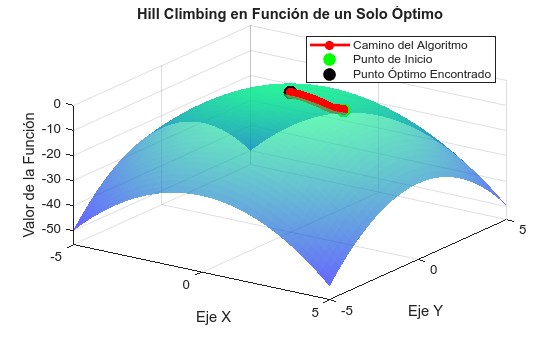


% 5. Visualización
figure; % Creamos una nueva figura
hold on; % Mantenemos los elementos gráficos en la misma figura
grid on;
title('Hill Climbing en Función de un Solo Óptimo');
xlabel('Eje X');
ylabel('Eje Y');
zlabel('Valor de la Función');
view(30, 45); % Ángulo de la vista 3D

% Graficamos la superficie de la función
[x, y] = meshgrid(limite_x(1):0.2:limite_x(2), limite_y(1):0.2:limite_y(2));
z = funcion_objetivo(x, y);
surf(x, y, z, 'FaceAlpha', 0.6, 'EdgeColor', 'none');
colormap(winter);

% Graficamos el camino que siguió el algoritmo
plot3(historial_puntos(:,1), historial_puntos(:,2), historial_puntos(:,3), ...
      'r-o', 'LineWidth', 2, 'MarkerFaceColor', 'r', 'MarkerSize', 5);

% Marcamos el punto de inicio y el punto final
plot3(historial_puntos(1,1), historial_puntos(1,2), historial_puntos(1,3), ...
      'go', 'MarkerFaceColor', 'g', 'MarkerSize', 10);
plot3(historial_puntos(end,1), historial_puntos(end,2), historial_puntos(end,3), ...
      'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 10);

legend('', 'Camino del Algoritmo', 'Punto de Inicio', 'Punto Óptimo Encontrado', 'Location', 'northeast');
hold off;